# Differential Equation

wiki: [https://en.wikipedia.org/wiki/Differential_equation](https://en.wikipedia.org/wiki/Differential_equation)

- Runge-Kutta methods

- Richardson extrapolation / Bulirsch-stoer method (TODO)

- predictor-corrector methods (TODO)

concept

- the degree of differential equation: the degree of the highest derivative

- linearity of the equation: linear or non-linear

- dynamical forms: the left hand side of the equation contains a function that depends only on the values of the various parameters and dynamic variables

ODE type

- initial value problems

- boundary value problems

Euler's method: [https://en.wikipedia.org/wiki/Euler_method](https://en.wikipedia.org/wiki/Euler_method)

Runge-Kutta's methods: [https://en.wikipedia.org/wiki/Runge%E2%80%93Kutta_methods](https://en.wikipedia.org/wiki/Runge%E2%80%93Kutta_methods)

## parameter

hf_ode = sample_ode(1, struct('mass',1,'spring_constant',1)); %harmonic motion
% hf_ode = sample_ode(2, struct('mass',1,'spring_constant',1,'damped_coeff',0.3)); %harmonic motion
% hf_ode = sample_ode(3, struct('a',1, 'b',-1));
y0 = rand(2,1);
t0 = 0;
t1 = 8*pi;

## Euler's method

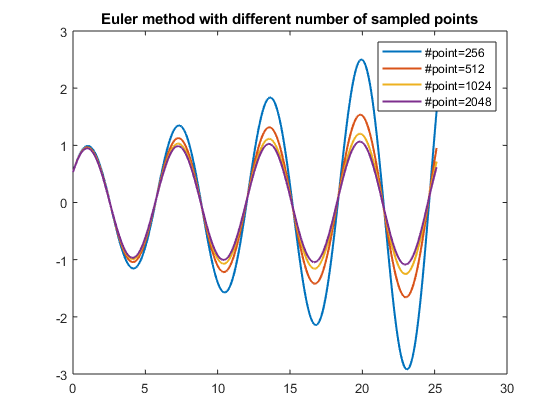

num_t = [256,512,1024,2048];
fig = figure();
ax = axes(fig, 'Box', 'on', 'NextPlot', 'add');
ax.Title.String = 'Euler method with different number of sampled points';
hLine = gobjects(size(num_t));
for ind1 = 1:numel(num_t)
    tmp1 = linspace(t0,t1,num_t(ind1));
    tmp2 = ode_euler(hf_ode, tmp1, y0);
    hLine(ind1) = plot(tmp1,tmp2(1,:), 'LineWidth', 1.5);
end
hf1 = @(x) ['#point=',num2str(x)];
legend(hLine,arrayfun(hf1,num_t,'UniformOutput',false));

## Runge-Kutta method

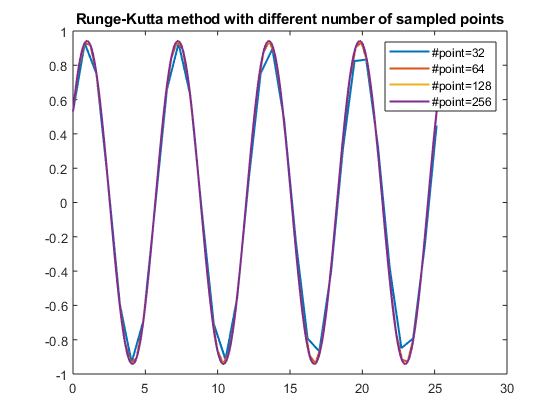

num_t = [32,64,128,256];
fig = figure();
ax = axes(fig, 'Box', 'on', 'NextPlot', 'add');
ax.Title.String = 'Runge-Kutta method with different number of sampled points';
hLine = gobjects(size(num_t));
for ind1 = 1:numel(num_t)
    tmp1 = linspace(t0,t1,num_t(ind1));
    tmp2 = ode_runge_kutta(hf_ode, tmp1, y0);
    hLine(ind1) = plot(tmp1,tmp2(1,:), 'LineWidth', 1.5);
end
hf1 = @(x) ['#point=',num2str(x)];
legend(hLine,arrayfun(hf1,num_t,'UniformOutput',false));

## Damped Harmonic Motion

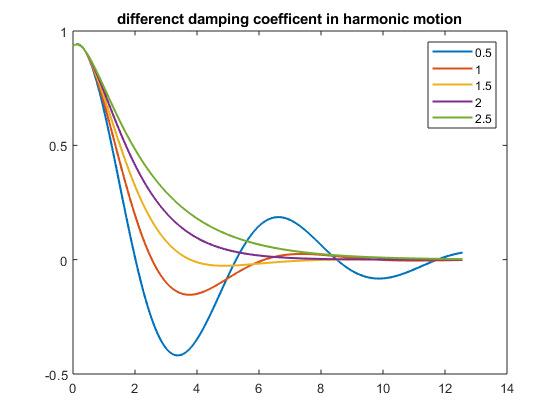

%% parameter
damped_coeff = [0.5,1.0,1.5,2,2.5];
y0 = rand(2,1);
t = linspace(0,4*pi,256);

fig = figure();
ax = axes(fig, 'Box', 'on', 'NextPlot','add');
ax.Title.String = 'differenct damping coefficient in harmonic motion';
hLine = gobjects(size(damped_coeff));
for ind1 = 1:numel(damped_coeff)
    hf1 = sample_ode(2, struct('mass',1,'spring_constant',1,'damped_coeff',damped_coeff(ind1)));
    tmp1 = ode_runge_kutta(hf1,t,y0);
    hLine(ind1) = plot(t,tmp1(1,:),'LineWidth',1.5);
end
hf1 = @(x) ['#point=',num2str(x)];
legend(hLine,arrayfun(@num2str,damped_coeff,'UniformOutput',false));

## Miscellaneous

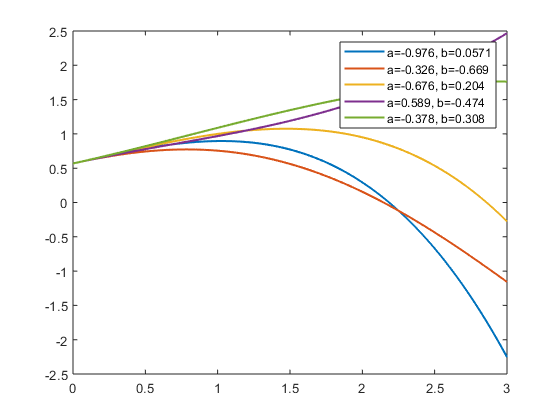

%% parameter
y0 = rand(2,1);
t = linspace(0,3,256);
para_a = 2*rand(1,5)-1;
para_b = 2*rand(1,5)-1;

%% figure
fig = figure();
ax = axes(fig,'NextPlot','add','Box','on');
ax.Title.String = 'miscellaneous with some random parameters'
hLine = gobjects(size(para_a));
for ind1 = 1:numel(para_a)
    hf1 = sample_ode(3, struct('a',para_a(ind1),'b',para_b(ind1)));
    tmp1 = ode_runge_kutta(hf1,t,y0);
    hLine(ind1) = plot(t,tmp1(1,:),'LineWidth',1.5);
end
tmp1 = arrayfun(@(x,y) ['a=',num2str(x,3),', b=',num2str(y,3)],para_a,para_b,'UniformOutput',false);
legend(hLine,tmp1);

function hf_differential = sample_ode(N1, para)
% N1[1,](1*1)
switch N1
    case 1 %harmonic motion
        % para(struct/spring_costant,mass)
        tmp1 = -para.spring_constant/para.mass;
        hf_differential = @(t,y) [y(2); tmp1*y(1)];
    case 2 %damped harmonic motion
        % para(struct/spring_costant,mass,damped_coeff)
        tmp1 = -para.spring_constant/para.mass;
        tmp2 = -para.damped_coeff/para.mass;
        hf_differential = @(t,y) [y(2); tmp1*y(1) + tmp2*y(2)];
    case 3 %mass
        % para(struct/a,b)
        hf_differential = @(t,y) [y(2);para.a*t + para.b*y(1)];
end
end

function ret = ode_euler(hf1,x,y0)
% solve ODE using Euler's method
% hf1(function handle): ((1,1),(N2,1))->(N2,1)
% x(1,N1): 
% y0(N2,1): initial value for at x(1)
% ret(N2,N1)
% reference: https://en.wikipedia.org/wiki/Euler_method
N1 = size(x,2);
N2 = size(y0,1);
ret = zeros(N2,N1);
ret(:,1) = y0;
for ind1 = 2:N1
    h = x(ind1)-x(ind1-1);
    ret(:,ind1) = ret(:,ind1-1) + hf1(x(ind1-1),ret(:,ind1-1))*h;
end
end

function ret = ode_runge_kutta(hf1,x,y0)
% solve ODE using Euler's method
% hf1(function handle): ((1,1),(N2,1))->(N2,1)
% x(1,N1): 
% y0(N2,1): initial value for at x(1)
% ret(N2,N1)
% reference: https://en.wikipedia.org/wiki/Runge%E2%80%93Kutta_methods
N1 = size(x,2);
N2 = size(y0,1);
ret = zeros(N2,N1);
ret(:,1) = y0;
for ind1 = 2:N1
    h = x(ind1) - x(ind1-1);
    tmp1 = x(ind1-1);
    tmp2 = ret(:,ind1-1);
    k1 = hf1(tmp1, tmp2);
    k2 = hf1(tmp1+h/2, tmp2+h*k1/2);
    k3 = hf1(tmp1+h/2, tmp2+h*k2/2);
    k4 = hf1(tmp1+h, tmp2+h*k3);
    ret(:,ind1) = tmp2 + h/6*(k1+2*k2+2*k3+k4);
end
end
